
%   script to create graphs and calculations of Disease:
%  modeled
%  
tspan=[0,365];
N0 = 9e6;
parts_susc = [0.1:0.02:1];
Niters = 1e2+1;
Niters_susc = length(parts_susc);
corrs = linspace(-1,1,Niters);
init_inf = 1e-2;
gamma=1/10;
gammaH=1/20;
R=3;

config conplete: 

Split into Params for ODE model.

beta=[0.05*R*gamma,0.15*R*gamma,R*gamma];
% params(6:7):
% P_H: probability to move into hospital once finished with I.
% P_H(1): probability of hospitalization from Susceptible.
% P_H(2): probability of hospitalization from non-Susceptible.
pH=[0.2,0.2/10]

pH =     0.2000    0.0200


% params(8:9):
% P_D: probability of death from hospital.
% P_D(1): death from Susceptible.
% P_D(2): death from non-susceptible.
pD=[0.2,0.05]

pD =     0.2000    0.0500


%param=[beta,gamma, gamma_H,P_H,P_D];
% param=[1e-1.*[0.1 0.4 0.98 0.5 0.8] 0.1 0.01 0.1 0.01];
% param=[1/N0.*[0.015 0.045 0.3] 0.1 0.05 0.2 0.02 0.2 0.05];
param=[beta/N0 gamma gammaH pH pD]

param =     0.0000    0.0000    0.0000    0.1000    0.0500    0.2000    0.0200    0.2000    0.0500


% betas = R*gamma/N0

config complete. initialize storage variables:

Hosp = zeros(Niters,Niters_susc ,4);
Dead = zeros(Niters,Niters_susc,4);
TtoMaxParts = zeros(Niters,Niters_susc,4);
TtoMaxHosp = zeros(Niters,Niters_susc);
Correlation = zeros(Niters,Niters_susc,1);

Main part: loop over Susceptible portion, and correlation.

for iter1 = 1:Niters
    for iter2 = 1:Niters_susc
%     [mat,C] = get_corr(1);
        C = corrs(iter1);
        mat = good_corr(C, parts_susc(iter2));
        sb = mat(1,2); snb = mat(1,1); nsnb = mat(2,1);nsb = mat(2,2);
        xinit = [sb*N0; snb*N0; nsnb*N0; nsb*N0; ones(4,1)*init_inf*N0/4; zeros(12,1)];
        xinit = xinit / sum(xinit) * N0; 
        
        [x,t]=SEIRodeSolver_YR(tspan,param,xinit);
        % plot(t,x,'LineWidth',2),grid on, xlabel('days'),shg
        
        % measure hospitalization for compartments
        [max_h,t_max_ind] = max(x(:,9:12));
        t_max_h = t(t_max_ind);
        Hosp(iter1,iter2,:) = max_h; %  ./ (x(1,1:4) + x(1,5:8));
        TtoMaxParts(iter1,iter2,:) = t_max_h;
        
        % measure hospitalization overall
         [~,t_max_ind] = max(sum(x(:,9:12),2));
        t_max_h = t(t_max_ind);
        TtoMaxHosp(iter1,iter2,:) = t_max_h;
        % 
        Dead(iter1,iter2,:) = x(end,17:20); %  ./ ((x(1,1:4) + x(1,5:8)).*reshape([pD;pD].*[pH;pH],1,4));
        Correlation(iter1,iter2) = (sb*nsnb - snb*nsb) / (sb*nsnb + snb*nsb);
%         snb_(iter1, iter2) = mat(1,1); sb_(iter1) = mat(1,2);
    end
end

Graph 1: Times of Max Hospitalization.

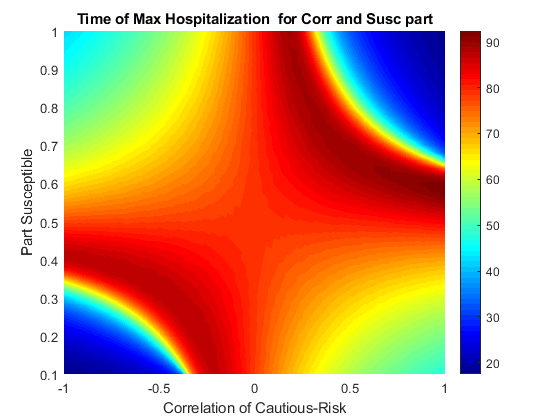

figure; pcolor(corrs', parts_susc', TtoMaxHosp'); shading interp ;
colormap jet
colorbar
xlabel("Correlation of Cautious-Risk")
ylabel("Part Susceptible")
title("Time of Max Hospitalization  for Corr and Susc part")

Graph 1.1: Amount of Dead for corr and susc

figure; subplot(2,4,[1 2 5 6]);
p1 = contourf(corrs', parts_susc', sum(Dead,3)',30,'linewidth',2); 
colormap jet
hold on; plot(corrs', 0.3*ones(length(corrs),1),"w--","linewidth", 3)
hold on; plot(corrs', 0.4*ones(length(corrs),1),"w--","linewidth", 3)
colorbar; hold on;
shading interp ;
xlabel("Correlation of Cautious-Risk", "FontSize",12)
ylabel("Percent at Risk", "FontSize",12)
title("Dead for Corr and Susc part")

% Graph 3: Correlation vs DEAd/Hosp by Group for a few [part susc]
subplot(2,4,[3 4]);
sval_to_plot = 0.3

sval_to_plot = 0.3000

[~,s_ind1] = min(abs(parts_susc-sval_to_plot))

s_ind1 = 11

load(".\agent res for 0.3 susc.mat")
plot(corrs,sum(Dead(:,s_ind1,:),3),'b','linewidth',3); hold on;
plot(res.corr,sum(t.Variables,2) * sf, 'b.'); hold on;

sval_to_plot = 0.4

sval_to_plot = 0.4000

[~,s_ind2] = min(abs(parts_susc-sval_to_plot))

s_ind2 = 16

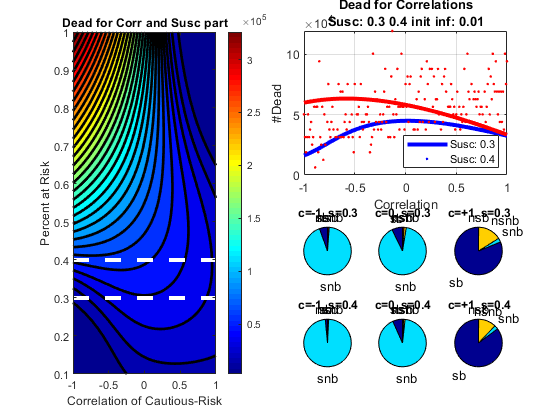

plot(corrs,sum(Dead(:,s_ind2,:),3),'r','linewidth',3); hold on
load(".\agent res for 0.4 susc.mat"); 
plot(res.corr,sum(t.Variables,2) * sf, 'r.'); hold on;
grid on
title(["Number of Dead";...
    "Risk: "+join(string(parts_susc([s_ind1 s_ind2])))+" init inf: "+init_inf])
xlabel("Correlation"); ylabel("#Dead");
legend(["Susc: 0.3" "Susc: 0.4"], 'Location',"southeast")
% Graph 4: Pie chart of which groups are dead for different s 0.3,0.4
ts = ["sb" "snb" "nsnb" "nsb"];
subplot(4,6,16); pie(Dead(1,s_ind1,:), ts); title("c=-1, s=0.3")
subplot(4,6,17); pie(Dead(Niters_susc/2,s_ind1,:), ts);title("c=0, s=0.3")
subplot(4,6,18); pie(Dead(end,s_ind1,:), ts);title("c=+1, s=0.3")
subplot(4,6,22); pie(Dead(1,s_ind2,:), ts);title("c=-1, s=0.4")
subplot(4,6,23); pie(Dead(Niters_susc/2,s_ind2,:), ts);title("c=0, s=0.4")
subplot(4,6,24); pie(Dead(end,s_ind2,:), ts);title("c=+1, s=0.4")

% savefig("figures\graph Dead 23.1.21.fig")

Graph 1.2: Amount of Dead for corr and susc

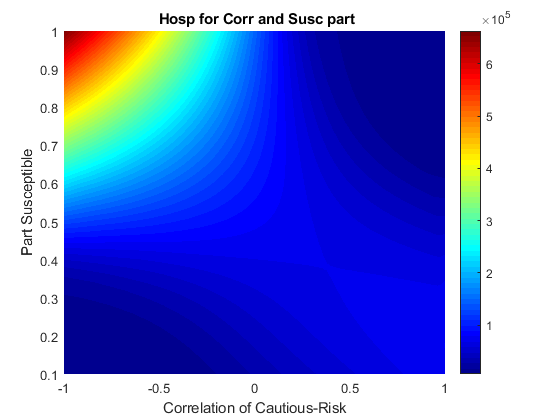

figure; pcolor(corrs', parts_susc', sum(Hosp,3)'); shading interp ;
colormap jet
colorbar
xlabel("Correlation of Cautious-Risk")
ylabel("Part Susceptible")
title(" Hosp for Corr and Susc part")

Graph 4: Hosp for corrs and susc.

f = figure; subplot(2,4,[1 2 5 6]);
p1 = contourf(corrs', parts_susc', sum(Hosp,3)',30,'linewidth',2); 
colormap jet
hold on; plot(corrs', 0.3*ones(length(corrs),1),"w--","linewidth", 3)
hold on; plot(corrs', 0.4*ones(length(corrs),1),"w--","linewidth", 3)
colorbar; hold on;
shading interp ;
xlabel("Correlation of Cautious-Risk")
ylabel("Part Susceptible")
title("Hospitalized for Corr and Susc part")

% Graph 3: Correlation vs DEAd/Hosp by Group for a few [part susc]
subplot(2,4,[3 4]);
sval_to_plot = 0.3

sval_to_plot = 0.3000

[~,s_ind1] = min(abs(parts_susc-sval_to_plot))

s_ind1 = 11

plot(corrs,sum(Hosp(:,s_ind1,:),3),'b','linewidth',3); hold on;
plot(res.corr,sum(t.Variables,2) * sf, 'k.'); hold on;
sval_to_plot = 0.4

sval_to_plot = 0.4000

[~,s_ind2] = min(abs(parts_susc-sval_to_plot))

s_ind2 = 16

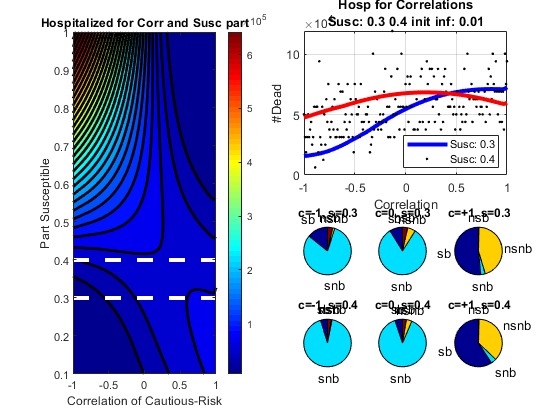

plot(corrs,sum(Hosp(:,s_ind2,:),3),'r','linewidth',3);
grid on
legend(["Susc: 0.3" "Susc: 0.4"], 'Location',"southeast")
title(["Hosp for Correlations";...
    "Susc: "+join(string(parts_susc([s_ind1 s_ind2])))+" init inf: "+init_inf])
xlabel("Correlation"); ylabel("#Dead")
% Graph 4: Pie chart of which groups are dead for different s 0.3,0.4
ts = ["sb" "snb" "nsnb" "nsb"];
subplot(4,6,16); pie(Hosp(1,s_ind1,:), ts); title("c=-1, s=0.3")
subplot(4,6,17); pie(Hosp(Niters_susc/2,s_ind1,:), ts);title("c=0, s=0.3")
subplot(4,6,18); pie(Hosp(end,s_ind1,:), ts);title("c=+1, s=0.3")
subplot(4,6,22); pie(Hosp(1,s_ind2,:), ts);title("c=-1, s=0.4")
subplot(4,6,23); pie(Hosp(Niters_susc/2,s_ind2,:), ts);title("c=0, s=0.4")
subplot(4,6,24); pie(Hosp(end,s_ind2,:), ts);title("c=+1, s=0.4")

% savefig("figures\graph Dead 23.1.21.fig")

Graph 2: Number of Dead for equalized parts.

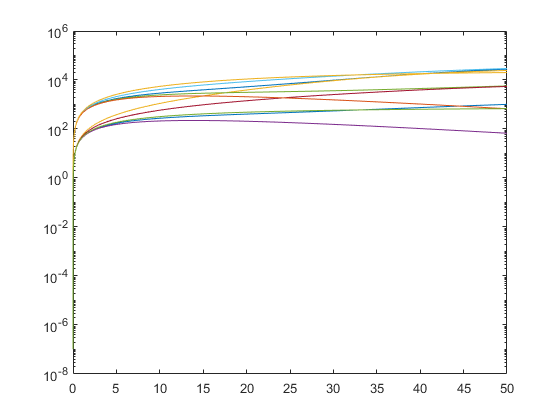

equality_S_val_dead = 0.348543421210721;
[~,x1,t1]=RunCorr(equality_S_val_dead,1,1);
[~,x0,t0]=RunCorr(equality_S_val_dead,0,1);
[~,x_1,t_1]=RunCorr(equality_S_val_dead,-1,1);
figure; semilogy(t1,x1(:,9:12)); hold on;
semilogy(t0,x0(:,9:12)); hold on;
semilogy(t_1,x_1(:,9:12)); xlim([0,50])

Graph 3: Dead and Hosp diff between +1 -1 Correlations for susceptibility 

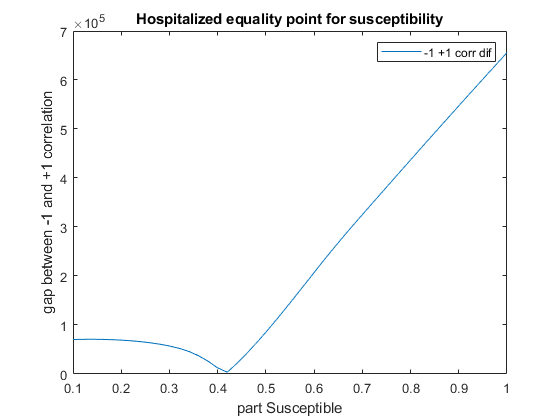

figure; plot(parts_susc,abs(sum(Hosp(1,:,:),3)-sum(Hosp(end,:,:),3)));
xlabel("part Susceptible")
ylabel("gap between -1 and +1 correlation")
title("Hospitalized equality point for susceptibility")
legend("-1 +1 corr dif")

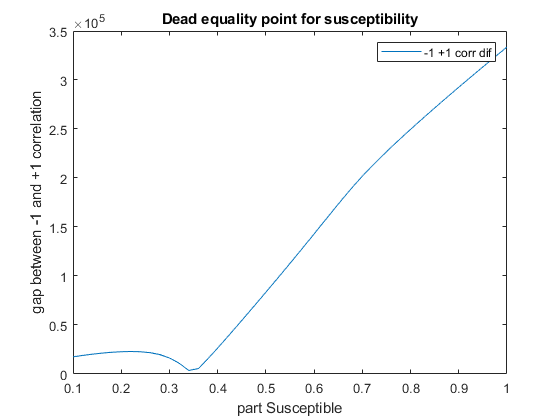

figure; plot(parts_susc,abs(sum(Dead(1,:,:),3)-sum(Dead(end,:,:),3)));
xlabel("part Susceptible")
ylabel("gap between -1 and +1 correlation")
title("Dead equality point for susceptibility")
legend("-1 +1 corr dif")

Graph 3: Correlation vs DEAd/Hosp by Group for a few [part susc]


[~,s_ind] = min(abs(parts_susc-equality_S_val_dead))

s_ind = 13

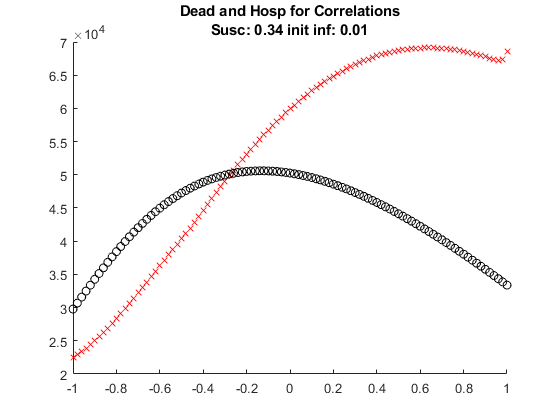

figure; scatter(corrs,sum(Hosp(:,s_ind,:),3),'rx'); hold on; 
scatter(corrs,sum(Dead(:,s_ind,:),3),'ko');
title(["Dead and Hosp for Correlations";"Susc: "+parts_susc(s_ind)+" init inf: "+init_inf])

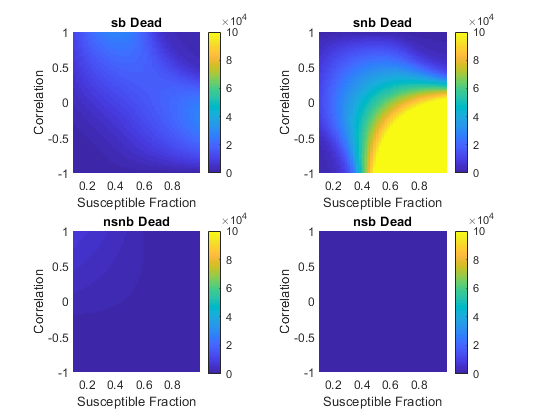

%%
ts = ["sb" "snb" "nsnb" "nsb"];
figure;
for i = 1:4
subplot(2,2,i); pcolor(parts_susc,corrs,Dead(:,:,i)); 
shading flat ; xlabel("Susceptible Fraction");
ylabel("Correlation");
title(ts(i)+" Dead"); colorbar;caxis([0 1e5]);
end

function [d,x,t] = RunCorr(Susc, C, d_or_h, param, N0, init_inf, tspan)
    if nargin == 2
        d_or_h = 0; %dead
    end
    if nargin <= 3
        N0 = 9000000;
        init_inf = 0.01;
        tspan = [0   365];
        param = [1.66e-09,5.00e-09,3.33e-08,0.100,0.0500,0.20,0.020,0.20,0.050];
    end
    
    if(d_or_h)
        inds = 9:12;
    else
        inds = 17:20;
    end
    mat = good_corr(C, Susc);
    sb = mat(1,2); snb = mat(1,1); nsnb = mat(2,1);nsb = mat(2,2);
    xinit = [sb*N0; snb*N0; nsnb*N0; nsb*N0; ones(4,1)*init_inf*N0/4; zeros(12,1)];
    xinit = xinit / sum(xinit) * N0; 
    [x,t]=SEIRodeSolver_YR(tspan,param,xinit);
    
    d = sum(x(end,inds),2);
    
end